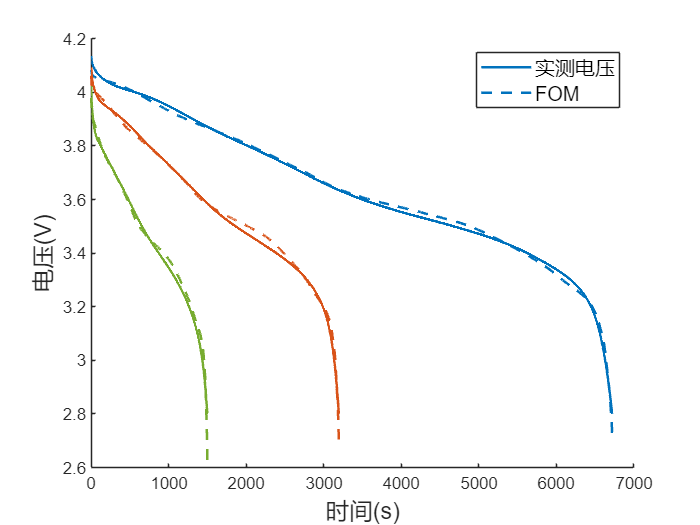

clear;
clc;
load cccv.mat;

c05_v=cccv.C05.vol;
c1_v=cccv.C1.vol;
c2_v=cccv.C2.vol;

c05_i=cccv.C05.cur/1000;
c1_i=cccv.C1.cur/1000;
c2_i=cccv.C2.cur/1000;

c05_t=(1:length(c05_v))';
c1_t=(1:length(c1_v))';
c2_t=(1:length(c2_v))';

% x=[0.2615,3.61137408174925,0.9856,2.70544455127934];

% x2=fminunc(@findrecc,[0.2615,3.61137408174925,0.9856,2.70544455127934],optimset)
x05=[0.260163301042261	3.32288380239572	0.952410641780617	2.73529870269589];
x=[0.252515743971892	3.28177424197287	0.968865101031026	2.75934524423781];
x2=[0.242664244758589	3.33204295972879	0.964987849444504	2.98474043471799];
V_fom05=ConstantDischarge(c05_i,x05);
V_fom=ConstantDischarge(c1_i,x);
V_fom2=ConstantDischarge(c2_i,x2);


figure(1);
clf;
hold on;
plot(c05_v,LineWidth=1.5,Color="#0072BD",LineStyle="-");
plot(V_fom05,LineWidth=1.5,Color="#0072BD",LineStyle="--");
plot(c1_v,LineWidth=1.5,Color="#D95319",LineStyle="-");
plot(V_fom,LineWidth=1.5,Color="#D95319",LineStyle="--");
plot(c2_v,LineWidth=1.5,Color="#77AC30",LineStyle="-");
plot(V_fom2,LineWidth=1.5,Color="#77AC30",LineStyle="--");
legend('实测电压','FOM',fontsize=12);
xlabel('时间(s)','fontsize',14);
ylabel('电压(V)','fontsize',14);

error(1,1)=RMSE(V_fom05,c05_v)*1000;error(1,2)=RMSE(V_fom,c1_v)*1000;error(1,3)=RMSE(V_fom2,c2_v)*1000;
error(2,1)=MAPE(V_fom05,c05_v);error(2,2)=MAPE(V_fom,c1_v);error(2,3)=MAPE(V_fom2,c2_v);